s0_add_paths;

## Summary

#### 0. Previous change: use multiple spatial frequency, use resized image

#### 1. The first attempt - no cross: 

- Using multiple spatial filters improve the fit performance

- The reparameterization trick doubles (tripples) the training speed

- The reparameterization trick may return imaginary loss; it may return negative denumerator, the exponent (<1) of which is an imaginary number

- Measurement 1: use "sqp" method   2. find the imag number and fix to inf

#### 2. The second attempt - no cross: 

- There is no imaginary loss is, but some fit are unresonably bad, especially ds 2, roi1, OTS model.

- This script explores the reason behind the extremely bad fit

#### 3. Possible solutions: use both 'classic' and 'reparam' method to do ensemable. 

## The loss landscape

% find the fit parameters
target = 'target'; ds = 2; roi = 1; n = 20;
model = oriSurroundModel('reparam'); model_idx = 3;
fit_param = dataloader(stdnormRootPath, 'param', target, ds, roi, 'noCross', model_idx, 'fmincon')

fit_param =     0.0714    0.0000   11.9391


wLst = linspace(.01, 0.1, n);
aLst = linspace(-5, 5, n);
mse_land = nan(n, n);

% input 
E = dataloader(stdnormRootPath, 'E_xy', target, ds, roi);
Z = dataloader(stdnormRootPath, 'Z1', target, ds, roi);

% output 
BOLD_tar = dataloader(stdnormRootPath, 'BOLD_target', target, ds, roi); 

for i = 1:n
    for j = 1:n
        fit_param(1) = wLst(i);
        opt_param(3) = aLst(j);
        BOLD_hat = model.forward(model, {E, Z}, fit_param);
        mse = double(mean((BOLD_tar - BOLD_hat).^2));
        mse_land(i, j) = mse;
    end
end

sp=4;
[loss_min_global, n] = min(mse_land(:));
loss_min_global

loss_min_global = 0.2110

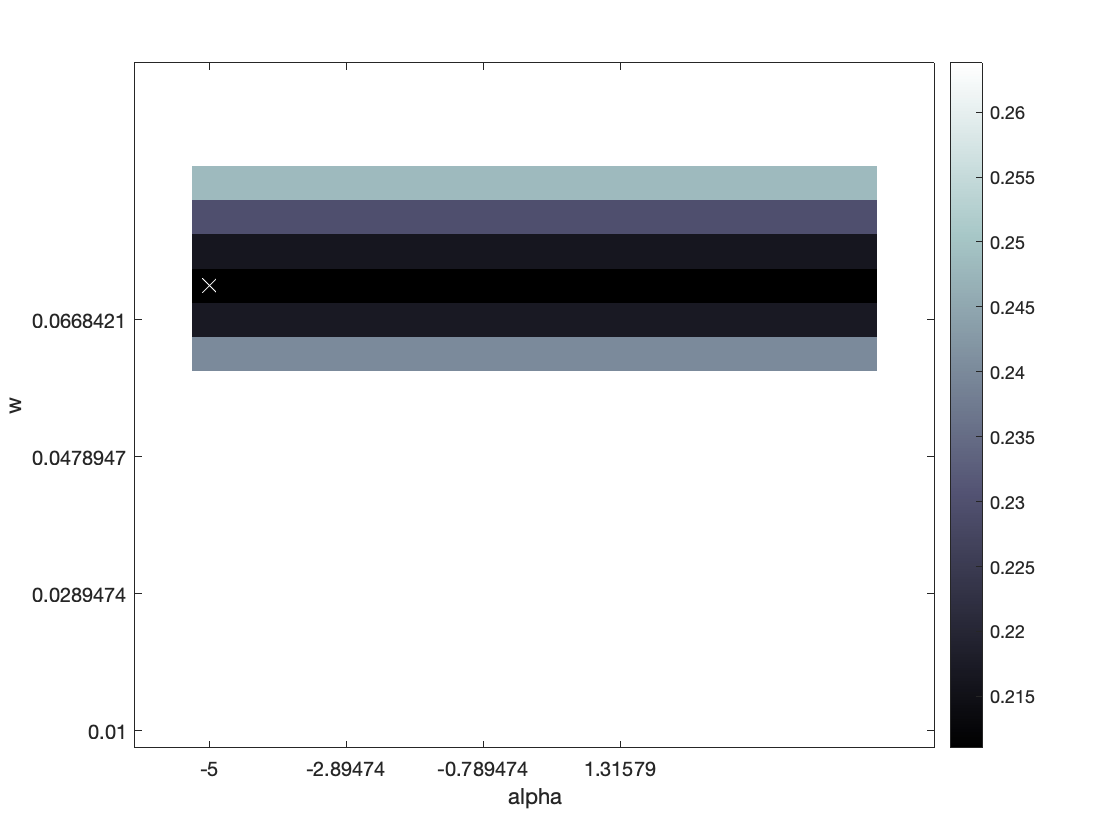

[y_min, x_min] = ind2sub(size(mse_land),n);
loss_min_global = min(mse_land(:));
figure();
imagesc(clip(mse_land, 0, loss_min_global*1.25));
set(gca,'YDir','normal')
colormap bone;
colorbar;
xticks(1:sp:n)
xticklabels(aLst(1:sp:n))
yticks(1:sp:n)
yticklabels(wLst(1:sp:n))
xlabel('alpha')
ylabel('w')
axis equal;
hold on
scatter(x_min, y_min, 80, [1,1,1], 'x')

## The fitted parameters of the classic model

% classic parameters 
sig   = 0.0365;
g     = 4.0304;
alpha = Sigmoid(-0.6607);
g_prime = g ^ (1/alpha);
b = sig / g_prime;
w = 1 / g_prime;
opt_param = [w, b, -0.6607]

opt_param =     0.0167    0.0006   -0.6607


BOLD_hat = model.forward(model, {E, Z}, opt_param);
mse = double(mean((BOLD_tar - BOLD_hat).^2))

mse = 0.0220

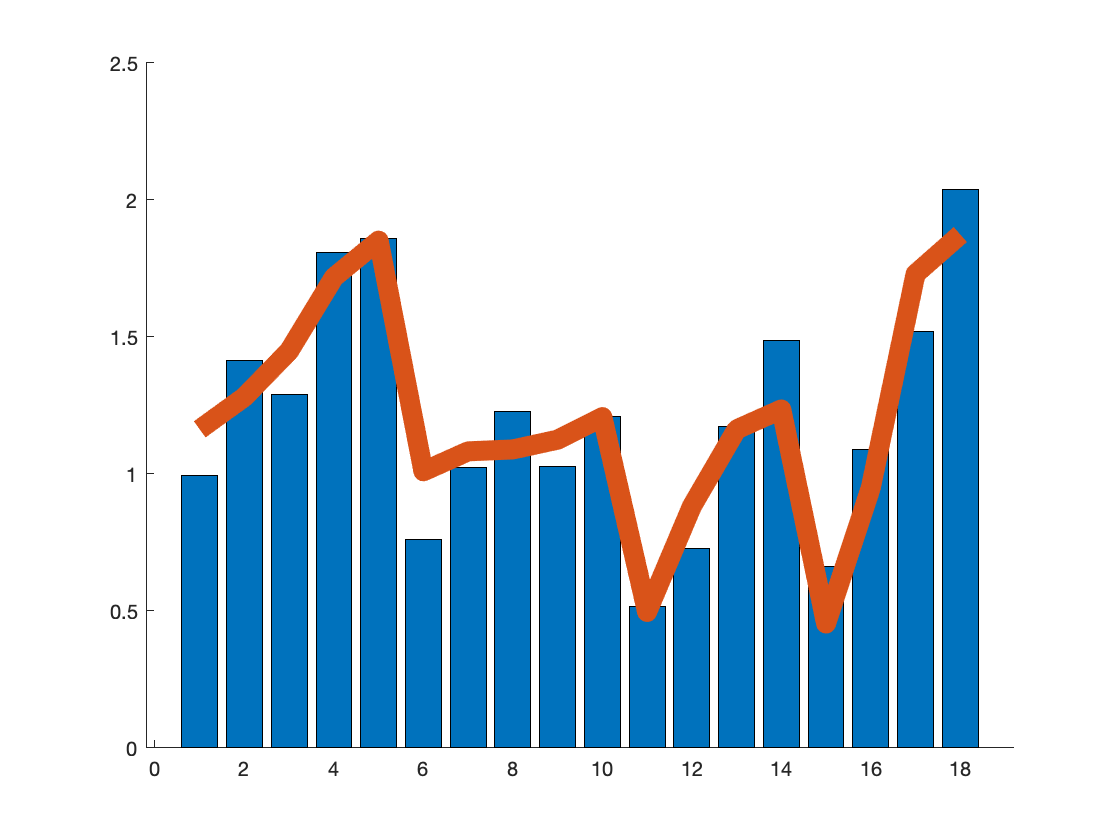

    0.0220



figure; hold on;bar(BOLD_tar); plot(BOLD_hat, "LineWidth", 10); disp(double(mean((BOLD_tar - BOLD_hat).^2)))

## The loss landscape

% parameters
wLst = linspace(.01, 0.2, n);
aLst = linspace(-1, 0, n);
mse_land = nan(n, n);

% input 
E = dataloader(stdnormRootPath, 'E_xy', target, ds, roi);
Z = dataloader(stdnormRootPath, 'Z1', target, ds, roi);

% output 
BOLD_tar = dataloader(stdnormRootPath, 'BOLD_target', target, ds, roi); 

for i = 1:n
    for j = 1:n
        opt_param(1) = wLst(i);
        opt_param(3) = aLst(j);
        BOLD_hat = model.forward(model, {E, Z}, opt_param);
        mse = double(mean((BOLD_tar - BOLD_hat).^2));
        mse_land(i, j) = mse;
    end
end

sp=3;
[loss_min_global, n] = min(mse_land(:));
loss_min_global

loss_min_global = 0.0277

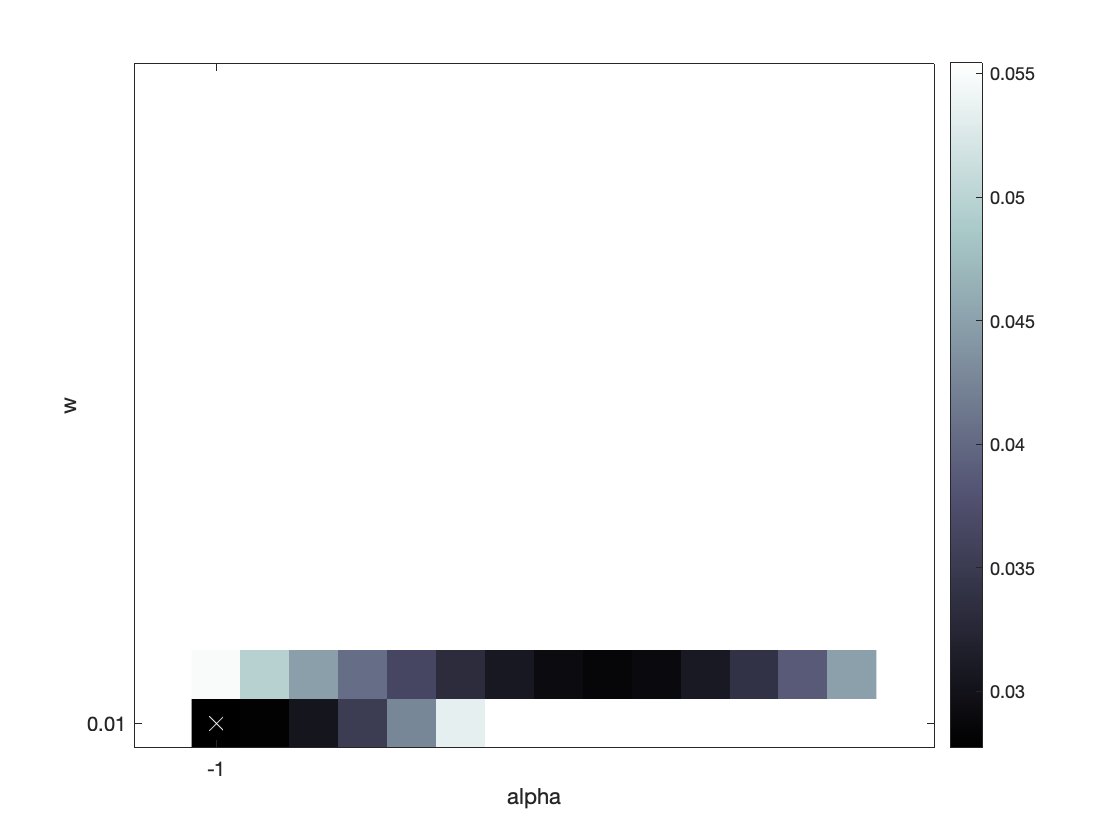

[y_min, x_min] = ind2sub(size(mse_land),n);
loss_min_global = min(mse_land(:));
figure();
imagesc(clip(mse_land, 0, loss_min_global*2));
set(gca,'YDir','normal')
colormap bone;
colorbar;
xticks(1:sp:n)
xticklabels(aLst(1:sp:n))
yticks(1:sp:n)
yticklabels(wLst(1:sp:n))
xlabel('alpha')
ylabel('w')
axis equal;
hold on
scatter(x_min, y_min, 80, [1,1,1], 'x')

function y = clip(x,bl,bu)
% return bounded value clipped between bl and bu
y=min(max(x,bl),bu);
end